Practica 1

Ejercicio 1: Muestreo

a)

T = t(2) - t(1)

T = 6.2500e-06

f_s_x = 1 / T

f_s_x = 160000

b) f_s_min >= 2 * f_muestreo

f_s_min = 2 * f_s_x % Porque f_s_x es la frecuencia de muestreo (viene del vector t)

f_s_min = 320000

c)

f_s_g = 3/2 * f_s_min

f_s_g = 480000

f_s_h = 2/3 * f_s_min

f_s_h = 2.1333e+05

t1 = t(1) : 1/f_s_g : t(end)

t1 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001


t2 = t(1) : 1/f_s_h : t(end)

t2 =          0    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0001    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002    0.0002


g = interp1(t, x, t1, 'spline')

g =     9.8505    5.7116    2.1744   -0.6116   -2.4970   -3.3323   -2.9681   -1.3528    1.1726    4.1690    7.2193    9.9926   12.1799   13.5137   13.8924   13.2563   11.6027    9.1567    6.2008    3.0470    0.1251   -2.1053   -3.2707   -3.3408   -2.3714   -0.4578    2.1450    5.1420    8.2386   11.1400   13.5517   15.2182   16.0419   15.9643   14.9445   13.0113   10.2112    6.7098    3.1503    0.2950   -1.2684   -1.6504   -1.1363    0.0468    1.9044    4.5000    7.7693   11.1370   13.9001   15.4842


h = interp1(t, x, t2, 'spline')

h =     9.8505    1.4017   -3.0553   -1.8591    4.1690   10.6065   13.8261   12.1014    6.2008   -0.5152   -3.4392   -1.0123    5.1420   11.8004   15.7391   15.2869   10.2112    2.3407   -1.5892   -0.3097    4.5000   11.9119   15.8074   13.6780    7.3421    0.2752   -4.0917   -2.0578    5.3158   11.1758   15.5857   16.1540   10.6660    2.5110   -1.5106    0.3045    6.1182   13.6103   17.2471   15.0186    8.2100   -0.0709   -3.0091   -1.0092    3.5533   11.3244   15.2264   13.2617    7.9326    1.8115


d)

X = fft(x, length(x)) ./ length(x);
G = fft(g, length(g)) ./ length(g);
H = fft(h, length(h)) ./ length(h);

Ahora hay que cambiar los vectores porque matlab ordena primero los valores positivos en la primera mitad y los negativos en la segunda

X_centrada = fftshift(abs(X));
G_centrada = fftshift(abs(X));
H_centrada = fftshift(abs(X));

Creamos los ejes de frecuencias

f_x = linspace(-f_s_x/2, f_s_x/2, length(X_centrada));
f_g = linspace(-f_s_g/2, f_s_g/2, length(G_centrada));
f_h = linspace(-f_s_h/2, f_s_h/2, length(H_centrada));

Ahora graficamos

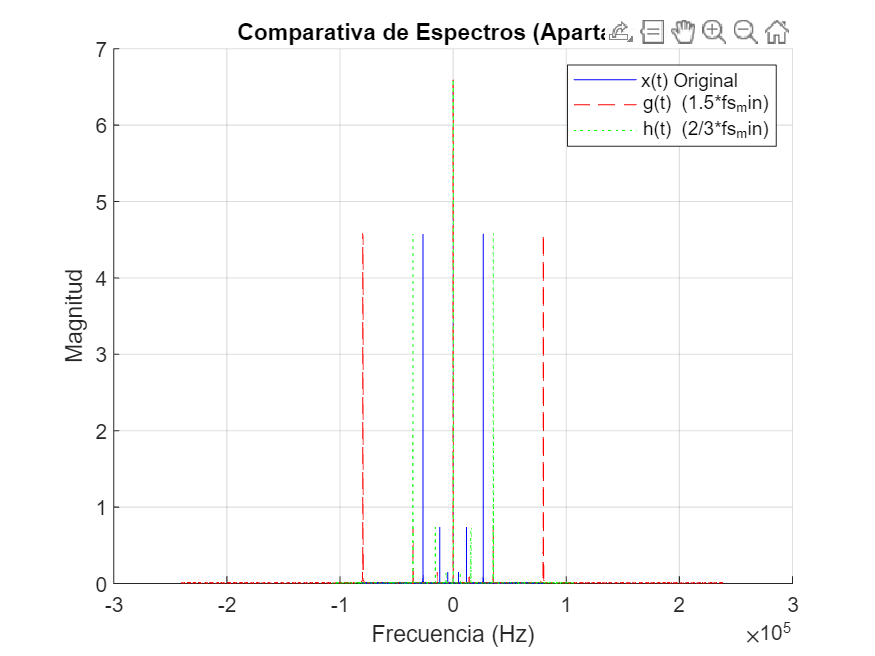

figure;
hold on;
plot(f_x, X_centrada, 'b');           % Señal original en azul
plot(f_g, G_centrada, 'r--');         % Señal g (fs > Nyquist) en rojo discontinuo
plot(f_h, H_centrada, 'g:');          % Señal h (fs < Nyquist) en verde puntos

grid on;
xlabel('Frecuencia (Hz)');
ylabel('Magnitud');
title('Comparativa de Espectros (Apartado d)');
legend('x(t) Original', 'g(t) (1.5*fs_min)', 'h(t) (2/3*fs_min)');

¿Qué es la energía de poca potencia que se ve en todo el rango de frecuencias?

Respuesta

e)

Sin zoom

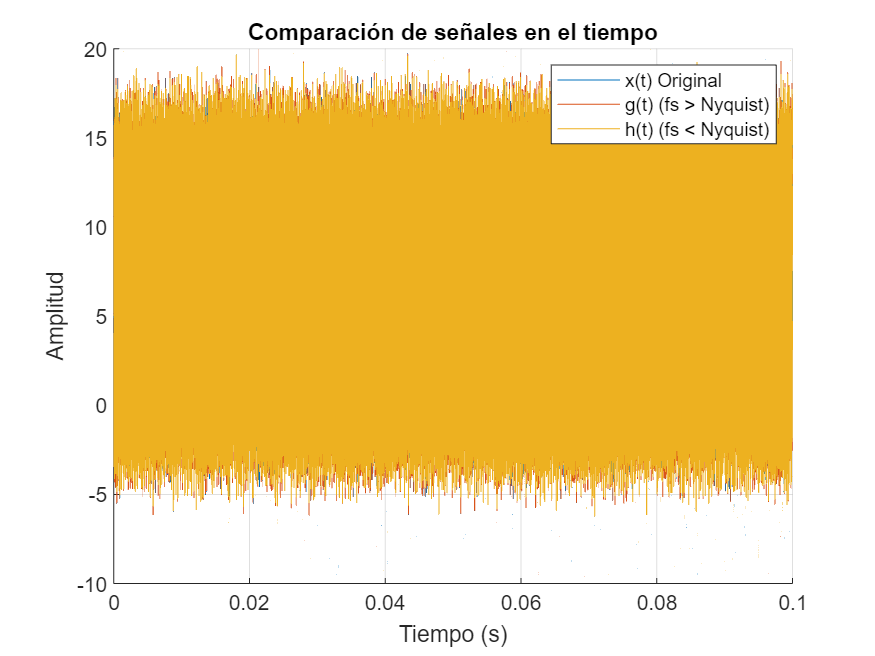

figure;
hold on;
plot(t, x);
plot(t1, g);
plot(t2, h);

grid on;
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Comparación de señales en el tiempo');
legend('x(t) Original', 'g(t) (fs > Nyquist)', 'h(t) (fs < Nyquist)');

Con zoom

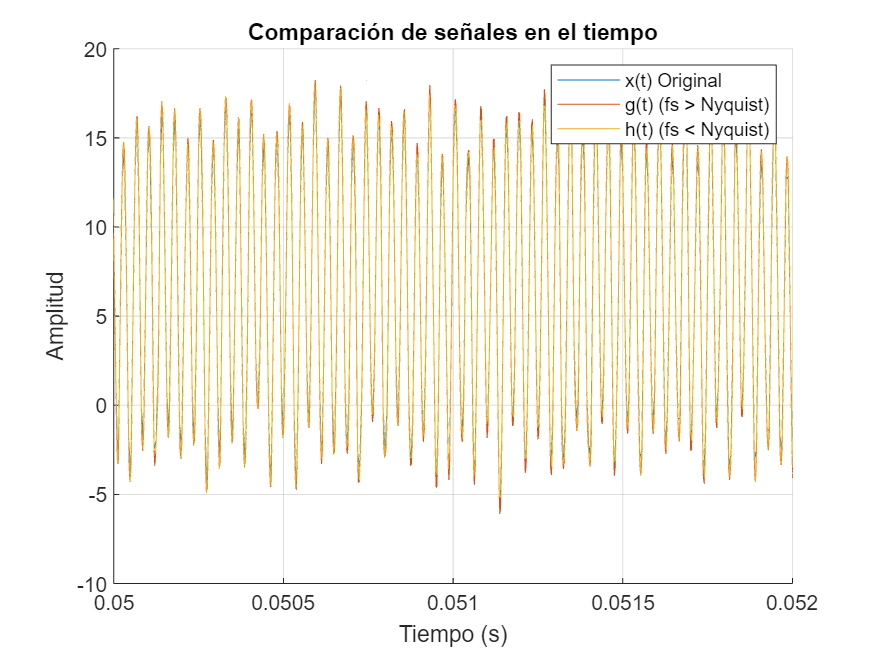

figure;
hold on;
plot(t, x);
plot(t1, g);
plot(t2, h);

grid on;
xlabel('Tiempo (s)');
ylabel('Amplitud');
title('Comparación de señales en el tiempo');
legend('x(t) Original', 'g(t) (fs > Nyquist)', 'h(t) (fs < Nyquist)');

xlim([0.05, 0.052]);

Ejercicio 2: Cuantización uniforme

1)